# The SIR Model

#### **The Model**

The SIR model is a compartmental model in epidemiology. A compartmental model divides the whole poulation in different groups and describes with a set of equations how the groups interact. In the SIR-model the three compartments are: the susceptible (S), the infected (I) and the removed (R). The flow of individuals from one compartment to another is described in terms of three differential equations, reported below, while the total number of the population stays the same in time: $N=S_0+I_0+R_0=S(t)+I(t)+R(t)$.

At initial conditions $S_0$, $I_0$ and $R_0$, the compartment S contains most of the population, whereas as little as 1 individual might account as infected and none belongs in the compartment R. As the disease spreads, individuals are relocated either from S to I when they contract the disease, or from I to R if they recover. It is assumed that immunity persists once it has been developed, that is, there is no flow from R to S.

The image below shows what the block diagram for the SIR model looks like.

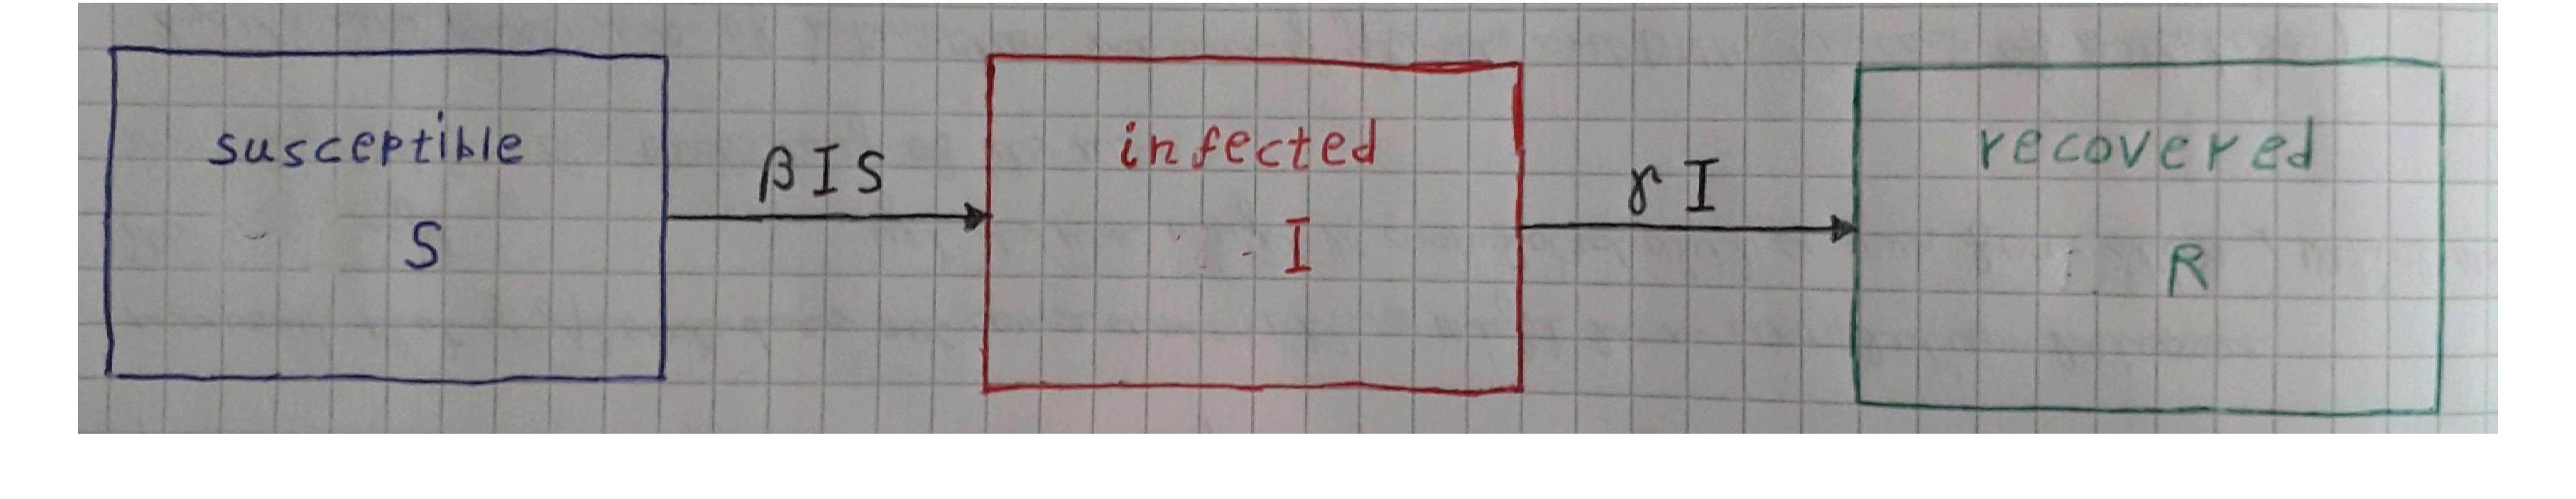

imshow('SIR_block_diagram.jpg')

The differential equations of the SIR model are:


$$\frac{dS}{dt}=-\beta I S,\\
\frac{dI}{dt}=\beta IS-\gamma I,\\
\frac{dR}{dt}=\gamma I.
$$


The parameters $\beta$ and $\gamma$are:

- $\beta$ is referred to as the infection rate and is defined as the product between the infection probability $p$ and the contact rate $c$, divided by the total population. In fact, its value depends on the transmissability of the disease, which is accounted for with $p$, and the frequency that members of a population gather for social reasons, which is expressed as $c$.

- $\gamma$ corresponds to the recovery rate. Its value relies on the virulence or pathogenicity of the organism responsible for the disease as well as the average physical and mental conditions of the population, which can also affect how drammatically an individual will experience related symptoms.

**The Basic Reproduction Number**

An important parameter in modelling of epidemics is the **basic reproduction number**, which is expressed as $\mathcal{R}_0$ and tells how many individuals (secondary cases) get infected by one person with the disease (oringinal case) at the beginning of an outspread. In other words,  $\mathcal{R}_0$ shows the level of contagiousness or infectiveness of a population unit in the S compartment. Here we derive $\mathcal{R}_0$:

At initial conditions, the rate of change in the fraction of infected can be defined as:

            $\left.\frac{dI}{dt} \right|_{t=0} = \beta I S - \gamma I$.

In order for an epidemics to take off, the expression above has to be greater than 0, so that the rate of change in number of infected individuals is positive and thus the infected fraction increases:

            
$$\beta I_0 S_0 - \gamma I_0 > 0 \quad\Longleftrightarrow\quad \beta I_0 S_0 > \gamma I_0 \quad\Longleftrightarrow\quad \frac{\beta S_0}{\gamma} > I_0$$


We can assume $S_0 \approx N$ and $I_0 = 1$, because at $t=0$ most of the population belongs to the compartment of susceptible and only one individual is contagious, the so-called *patient zero*. This assumption leads to the definition of the reproduction number:

            
$$\Longrightarrow \mathcal{R}_0= N \frac{\beta}{\gamma}>1$$


As we can see, $\mathcal{R}_0$ depends on the two parameters $\beta$ and $\gamma$, which epidemiological policies attempt to adjust in order to control the spread of an infectious disease.

However, $\mathcal{R}_0$ can also take on values smaller than or equal to 0. In this direction, the basic reproduction number can be employed as a threshold parameter for the establishment of **herd immunity** within the community of interest. If $\mathcal{R}_0 < 1$, one infected person can spread the disease to less than one population unit, thus herd immunity is achieved over time, whereas if $\mathcal{R}_0>1$, one infected person will spread the disease to more than one population unit and herd immunity is hindered. Finally, if $\mathcal{R}_0 =1$, the disease will endemically persist in the population for an undetermined timelapse.

            $\mathcal{R}_0<1$: establishment of herd immunity

            $\mathcal{R}_0=1$: endemic state

            $\mathcal{R}_0>1$: outbreak of the disease

Importantly, $\mathcal{R}_0$ does not stay constant across outbreaks of the same disease, as it depends on several environmental as well as social factors that vary across communities, regions and history.

**The Peak of the Epidemics**

Like the basic reproduction number, the peak of an outbreak is an element which can also arise a huge interest and affect policies as well as behavioural and psychological conditions of the population. Let's derive it starting from the expression for the derivative of $I$ with respect to $S$. This is convenient because we will then have to integrate:

            $\frac{dI}{dS}=-\frac{(\beta S - \gamma)I}{\beta I S}=-1+\frac{N}{\mathcal{R}_0 S}$.

Because the peak of infected corresponds to the maximum of its curve, $S_{peak}$ can be derived by equating $\frac{dI}{dt} = 0$ as follows:


$$\beta I S - \gamma I = 0$$
  
$$\Longleftrightarrow$$
  
$$I(\beta S - \gamma) = 0$$
  
$$\Longleftrightarrow$$
  
$$\beta S - \gamma = 0$$
  
$$\Longleftrightarrow$$
  
$$S_{peak} = \frac{\gamma}{\beta} = \frac{N}{\mathcal{R}_0}$$


We can now separate the variables and integrate the left side over $dI$ from 0 to $I_{max}$ and the right side over $dS$ from $S_0 \approx N$ to $S_{peak}=\frac{N}{\mathcal{R}_0}$:

            
$$\int_0^{I_{max}}{dI}=\int_N^{\frac{N}{\mathcal{R}_0}}{\left(-1+\frac{N}{\mathcal{R}_0 S}\right)dS$$


from which we obtain the **maximum value of infected individuals, which **is represented with $I_{max}$:

            
$$I_{max}= \left.\left(-S+ \frac{N}{\mathcal{R}_0}\ln S\right)\right|_N^{\frac{N}{\mathcal{R}_0}}=-\frac{N}{\mathcal{R}_0}+N+\frac{N}{\mathcal{R}_0} \left(\ln{\frac{N}{\mathcal{R}_0}}-\ln{N}\right)$$


We can further simplify $I_{max}$ into the following expression:

            
$$I_{max}=N-\frac{N}{\mathcal{R}_0}+\frac{N}{\mathcal{R}_0} \ln{\frac{1}{\mathcal{R}_0}}=\frac{N}{\mathcal{R}_0} \left(\mathcal{R}_0-1- \ln{\mathcal{R}_0} \right)$$


## Solution with Euler method

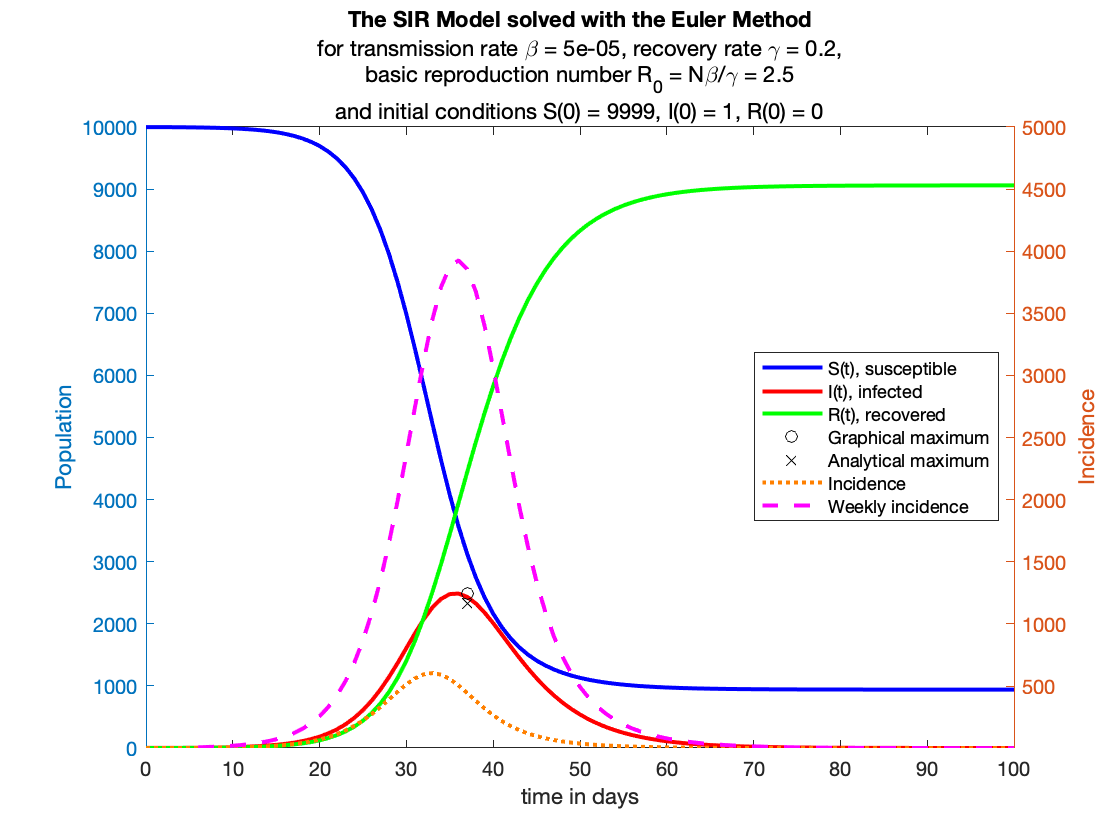

figure;

%%% The initial values

tmax = 100;

S = zeros(1, tmax + 1);
I = zeros(1, tmax + 1);
R = zeros(1, tmax + 1);

S(1) = 9999;
I(1) = 1;
R(1) = 0;
N=S(1)+I(1)+R(1);

Incidence = zeros(1, tmax + 1);
Incidence(1) = 0;

Weekly_Incidence = zeros(1, tmax - 6);

%%% The parameters

p=0.1;  % infection probability 
c=5;    % contact rate

beta = p*c/N;
gamma = 0.2;

R_0=beta*N/gamma;

%%% The Euler method

T = zeros(1,tmax + 1);
T(1) = 0;

for t = 1:tmax
        
    T(t+1) = t;
        
    S(t+1) = S(t) - beta*I(t)*S(t) ;   
    I(t+1) = I(t) + (beta*I(t)*S(t)) - gamma*I(t);    
    R(t+1) = R(t) + gamma*I(t);
    
    Incidence(t+1) = beta*I(t)*S(t);
    
        if t > 5
                
            Weekly_Incidence(t-5) = sum(Incidence(t-5:t+1));
            
        end
end

%%%% The maximum number of infected

analytical_Imax = N / R_0 * (R_0 - 1 - log(R_0));
graphical_Imax = max(I);

peak_time = find(I == graphical_Imax);

%%%% The plot

yyaxis left
plot(T, S, 'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(T, I, 'r','LineWidth',2,'LineStyle',"-");
plot(T, R, 'g','LineWidth',2,'LineStyle',"-");
plot(peak_time, graphical_Imax, 'ko')
plot(peak_time, analytical_Imax, 'kx')
ylabel('Population');

yyaxis right 
plot(T, Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(T(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylim([1 5000]);
ylabel('Incidence');

title('The SIR Model solved with the Euler Method')
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
['basic reproduction number R_0 = N\beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(S(1)),', I(0) = ',num2str(I(1)),', R(0) = ',num2str(R(1))]})
legend('S(t), susceptible', 'I(t), infected', 'R(t), recovered', 'Graphical maximum', 'Analytical maximum', 'Incidence', 'Weekly incidence', 'Location', 'east')

xlabel('time in days');
xlim([0 100]);
hold off

## Solution with ode45

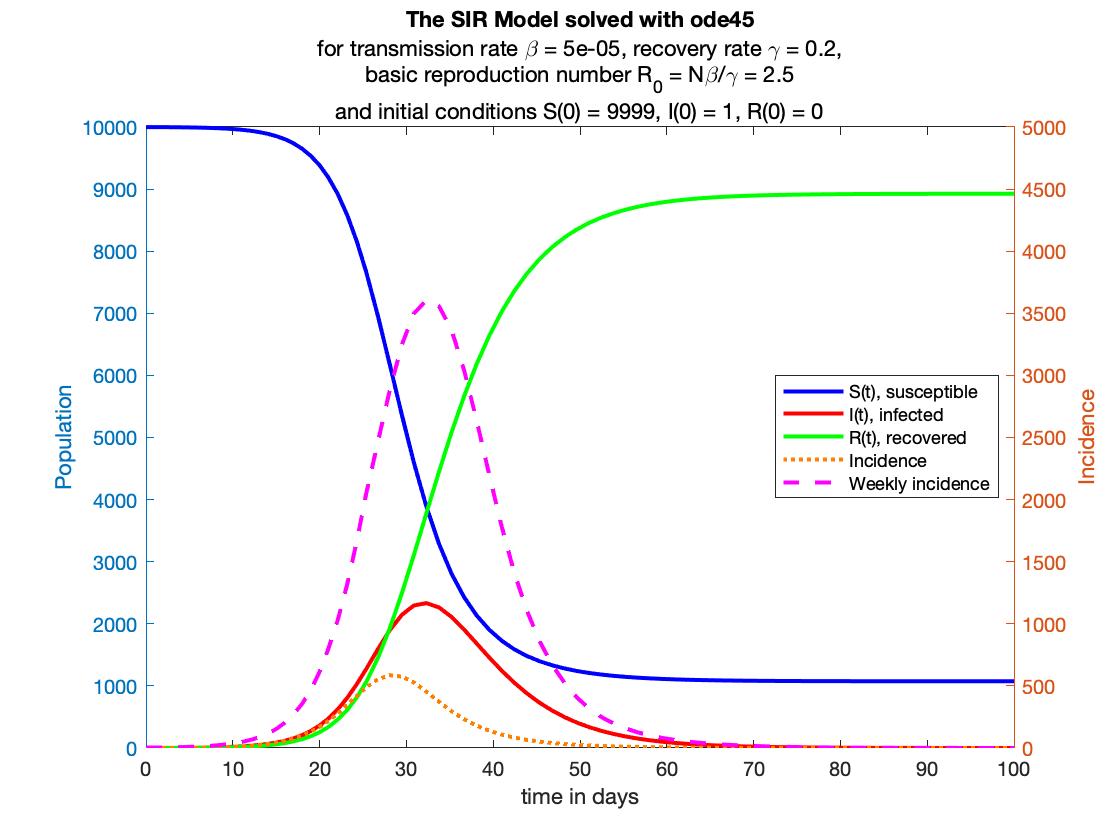

figure;

%%%% The parameters and the initial values

tRange = [0 100];
gamma = 0.2;
beta = 0.00005;

Y0 = [9999; 1; 0];

N=Y0(1)+Y0(2)+Y0(3);
R_0=beta*N/gamma;

[tSol,YSol] = ode45(@SIRmodel,tRange,Y0);

%%%% The plot

S = YSol(:,1);
I = YSol(:,2);
R = YSol(:,3);

Incidence = beta*S.*I;

sz = size(tSol);
Weekly_Incidence = zeros(sz(1)-6,sz(2));

for n = 7:sz(1)

    Weekly_Incidence(n-6) = sum(Incidence(n-6:n));
 
end

yyaxis left
plot(tSol,S,'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(tSol,I,'r','LineWidth',2,'LineStyle',"-");
plot(tSol,R,'g','LineWidth',2,'LineStyle',"-");
ylabel('Population');

yyaxis right
plot(tSol,Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(tSol(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylabel('Incidence');
ylim([0 5000]);

legend('S(t), susceptible', 'I(t), infected', 'R(t), recovered','Incidence', 'Weekly incidence', 'Location', 'east');
title('The SIR Model solved with ode45');
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = N\beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(Y0(1)),', I(0) = ',num2str(Y0(2)),', R(0) = ',num2str(Y0(3))]})

xlabel('time in days');
xlim([0 100]);

hold off;

## Phase Diagram

A **phase profile** or **phase diagram** illustrates the behavioural trend that a dynamical system undergoes as time goes by. In the case of an SIR model, a phase diagram depicts the number of infected individuals $I$ against the number of susceptible $S$. The resulting curve shows how the numbers of susceptible and infected cases interactively vary as the epidemics develops, starting from the bottom right corner, up along the curve and down to the bottom left corner of the graph.

In addition, the maximal number of infected can be estimated by looking at the maximum of the curve, which falls close to 2300 cases and is associated with a number of around 4000 susceptible individuals. In other words, the model disease hits a peak of roughly 2300 infected when about 4000 people have not yet contracted the disease.

Finally, the steepness of the curve hints for how fast the disease is spreading or diying off at that given point in terms of $S$ and $I$.

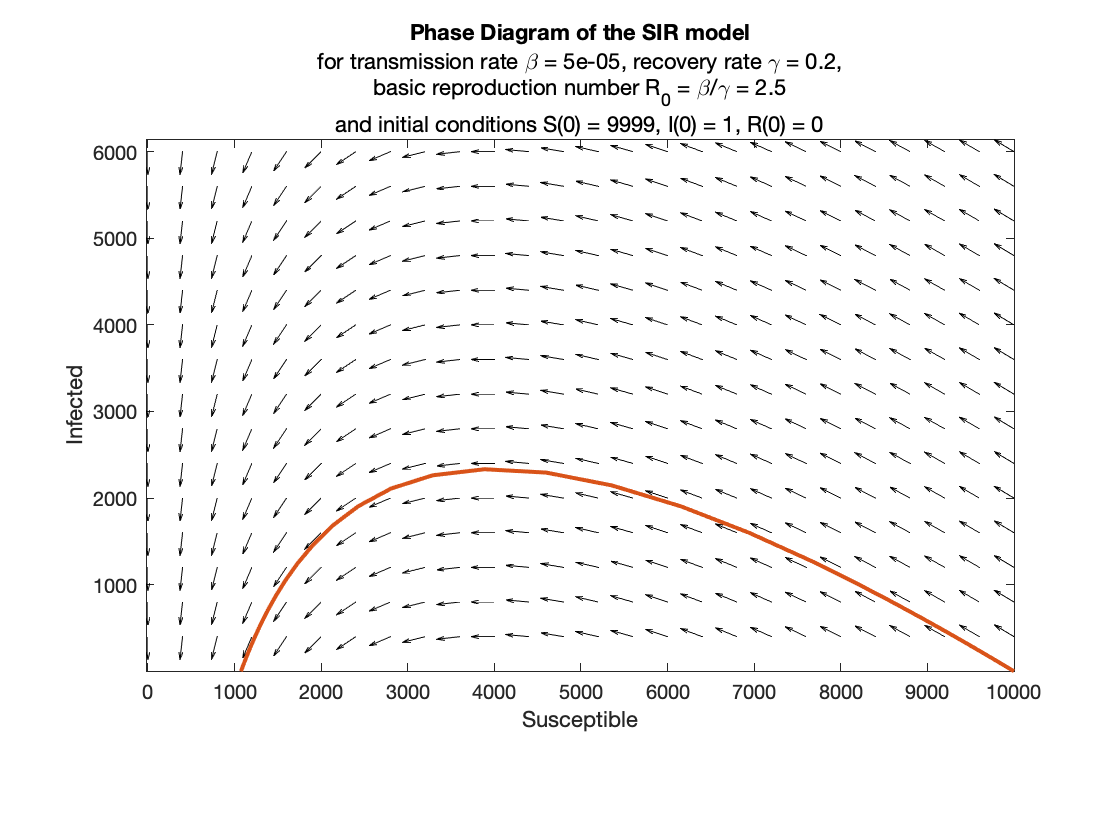

figure

%%vector field
[s, i]= meshgrid (0:400:10000, 0:400:6000);
U = -beta .* s .* i;
V = beta .* s .* i - gamma * i;
L = sqrt(U.^2 + V.^2);
quiver(s, i, U./L, V./L, 0.5, 'k')
axis equal tight

%%%% The solution on the plot
hold on
plot(S,I, 'LineWidth', 2)

xlabel('Susceptible')
ylabel('Infected')

title('Phase Diagram of the SIR model')

subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
    ['basic reproduction number R_0 = \beta/\gamma = ',num2str(R_0)], ...
    ['and initial conditions S(0) = ',num2str(Y0(1)),', I(0) = ',num2str(Y0(2)),', R(0) = ',num2str(Y0(3))]})
hold off

function dYdt = SIRmodel(~,Y)

    % Extract S, I, and R from input vector Y
    S = Y(1); % susceptible
    I = Y(2); % infected
    R = Y(3); % recovered
    
    % Define the constants beta and gamma
    beta = 0.00005;
    gamma = 0.2;
    
    % Define dSdt, dIdt, dRdt from the ODEs
    dSdt = -beta*S*I;
    dIdt = beta*S*I - gamma*I;
    dRdt = gamma*I;
    
    % Create output column vector dYdt
    dYdt = [dSdt; dIdt; dRdt];
    
end